## See also (in Python): [https://colab.research.google.com/drive/14Ws9gX1hPzBkE7P1sBepVuoz-uo2f-Be?usp=sharing#scrollTo=cEbiyY7g_laK](https://colab.research.google.com/drive/14Ws9gX1hPzBkE7P1sBepVuoz-uo2f-Be?usp=sharing#scrollTo=cEbiyY7g_laK)

## Synthèse d'une sinusoïde de fréquence 100 Hz

clc;
figure;
subplot(1, 1, 1);

## Computation of the sinewave and display

fs = 16000; % Sampling Freq.
dur = 3; % Sound duration in s.
t = linspace(0, dur, dur*fs);
freq = 220;
amp = 1;
phase = 0;

snd = amp .* sin(2*pi*freq.*t + phase);
t = t';
snd = snd';
% Ramp the sound extremities
snd = zeroends(snd, fs);

plot(t, snd);

### Display of a subset (N periods) that is outside the ramping parts

nperiods = 5;
start = 100;
select = round((start*((fs/freq))):((start+nperiods)*((fs/freq))));

figure;
subplot(1, 1, 1);
plot(t(select), snd(select));

## Play and save the sound wave

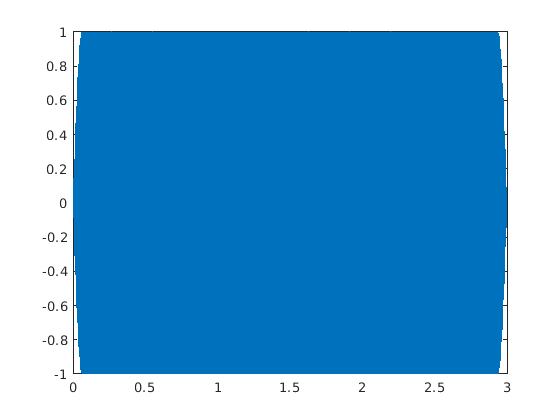

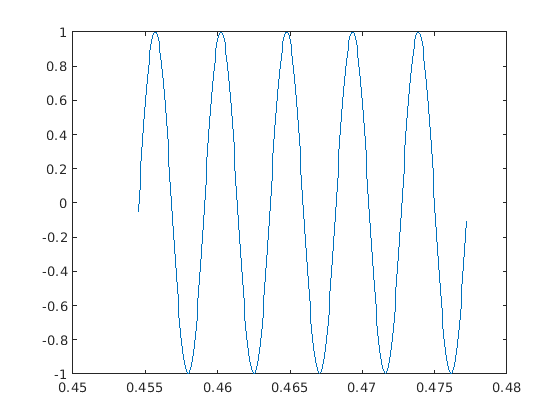

%soundsc(snd, fs);
%pause(dur);

listen = audioplayer(snd, fs);
playblocking(listen);

## Generate an amplitude modulation: 1 Hertz (1 cycle par seconde, Sinewave AM)

AMf1 = 1; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.5; % AM depth as a proportion of the carrier amplitude
AMphase1 = 1*pi;
mod = 1/2*AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1);

% Compute effective modulation depending on depth
mod = mod + (1 - max(mod));

final = mod .* snd;
final = zeroends(final, fs);
%final = modulate(snd, AMf, fs, 'am');


## Affichage

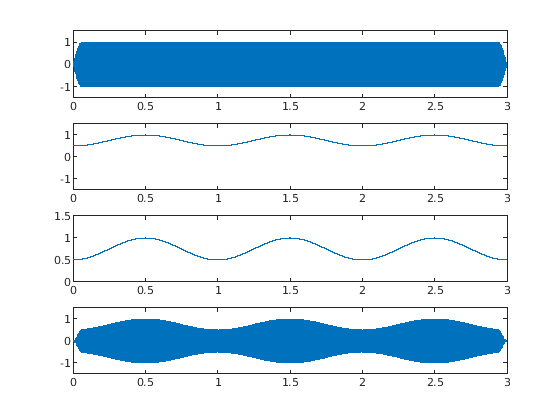

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, mod);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);

## Restriction à une période de l'enveloppe

extract = final(1:(AMf1*fs));
listen = audioplayer(extract, fs);
playblocking(listen);


## Generate an amplitude modulation: 6 Hertz (6 cycles par seconde, Sinewave AM)

AMf1 = 6; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.5; % AM depth as a proportion of the carrier amplitude
AMphase1 = 1*pi;
mod = 1/2*AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1);

% Compute effective modulation depending on depth
mod = mod + (1 - max(mod));

final = mod .* snd;
final = zeroends(final, fs);
%final = modulate(snd, AMf, fs, 'am');


## Affichage

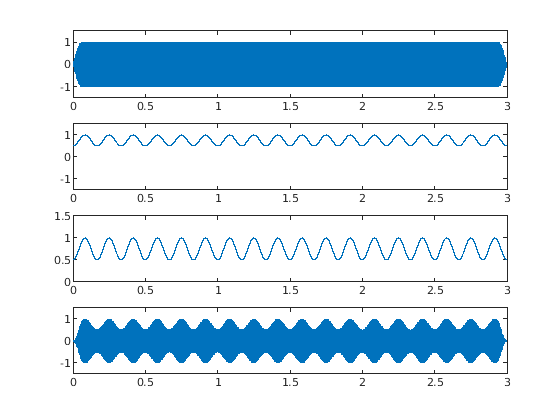

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, mod);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);

## Restriction à une période de l'enveloppe

extract = final(1:round(1/AMf1*fs));
listen = audioplayer(extract, fs);
playblocking(listen);


## Generate a multiple frequency amplitude modulation: 1 and 12 Hertz (1 and 12 cycles par seconde, Sinewave AM)

AMf1 = 1; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.95; % AM depth as a proportion of the carrier amplitude
AMphase1 = 1*pi;
AMf2 = 12; % Amplitude modulation frequency in Hertz
AMdepth2 = 0.75; % AM depth as a proportion of the carrier amplitude
AMphase2 = 1*pi;
mod = 1/2*AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1) + 1/2*AMdepth2 .* cos(2*pi*AMf2.*t + AMphase2);

% Compute effective modulation depending on depth
mod = mod + (1 - max(mod));

final = mod .* snd;
final = zeroends(final, fs);
%final = modulate(snd, AMf, fs, 'am');


## Affichage

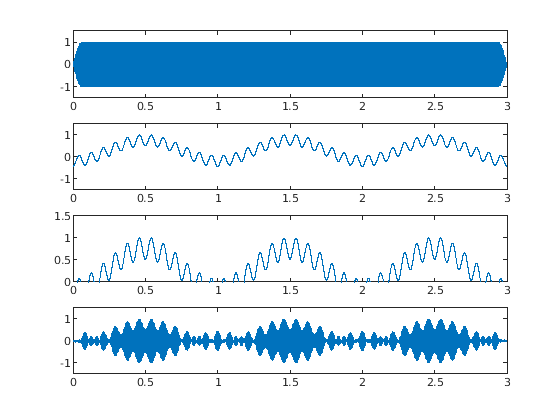

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, mod);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);

## Computation of the amplitude modulation spectrum (using the Voicebox toolbox)

addpath('~/work/src/github/others/voicebox/sap-voicebox/voicebox')
%target = final; % Better use it on speech...
[speech, sfs] = audioread('~/work/sounds/databases/lscp/french/frl1151.aiff');
[c,qq,ff,tt,po] = v_modspect(speech, sfs, 'gMALfS');

## Computation of the amplitude modulation spectrum (using the AAA (Acoustics, Auditory and A1 Cortex) toolbox, cf. paper by Ediz Sohoglu, Essex University, on AM freq. LP filtering)

addpath('work/lib/matlab/contrib/AAA');
loadload;
%[x, fs] = audioread('_come.au');
x = speech;
x = unitseq(x); % ?? on x or on xh?
xh = schematc(x);

y = wav2aud(x, paras);
aud_plot(y, paras);


z = aud2cors(y(60,:), sv);
cor_plts(z, sv, paras);

fcorname = '_come.cor';
cr = aud2cor(y, paras, rv, sv, fcorname);

rst = cor2rst(fcorname);
rst_view(rst, rv, sv);
colormap(jet);
rst_view(rst, rv, sv);
rst_view(rst, rv, sv, 1);
rst_view(rst, rv, sv, 2);
rst_view(rst, rv, sv, 3);
rst_view(rst, rv, sv, 3, 0.5);
rst_view(rst, rv, sv, 3, 0.9);
rst_view(rst, rv, sv, 3, 0.75);
rst_view(rst, rv, sv, 3, 0.5, 0);
rst_view(rst, rv, sv, 3, 0.5, 1);
rst_view(rst, rv, sv, 3, 0.5, 2);

rst_view(rst, rv, sv, 0, 0.5, 2);
rst_view(rst, rv, sv, 0, 1, 2);
rst_view(rst, rv, sv, 0, 1, 1);
rst_view(rst, rv, sv, 0, 1, 0);
rst_view(rst, rv, sv, 0, 1, 3);
rst_view(rst, rv, sv, 0, 1, 0);
rst_view(rst, rv, sv, 0, 1, 0, 1);
rst_view(rst, rv, sv, 0, 1, 0, 2);
rst_view(rst, rv, sv, 0, 1, 0, 0);
rst_view(rst, rv, sv, 0, 1, 0);
rst_view(rst, rv, sv, 0, 1, 3);
rst_view(rst, rv, sv, 0, 1, 2);
rst_view(rst, rv, sv, 0, 1, 1);
rst_view(rst, rv, sv, 0, 1, 0);
rst_view(rst, rv, sv, 0, 0, 0);
rst_view(rst, rv, sv, 0, 1, 0);
rst_view(rst, rv, sv, 0, 2, 0);

rst_view(rst, rv, sv, 1, 1, 0);

rst_view(rst, rv, sv, 2, 1, 0);

rst_view(rst, rv, sv, 3, 1, 0);
rst_view(rst, rv, sv, 3, 0.1, 0);
rst_view(rst, rv, sv, 3, 0.5, 0);

h_sub = [subplot(121), subplot(122)]
h_sub(1)
h_sub(2)
subplot(121)
xlabel('Modulation Frequency (in Hz)');
ylabel('Conventional Frequency (in kHz)');

## Computation of the amplitude modulation spectrum (using tools from Columbia University that were inspired by Les Atlas' work)

addpath('~/work/learning/sigproc/ModulationSpectrum/modcodec')

% Define the hop lengths in milliseconds
fhop1ms = 10;
fhop2ms = 250;

% Convert from ms to samples
fhop1 = round(fhop1ms*sfs/1000);
fhop2 = round(fhop2ms*sfs/(fhop1*1000));

% Do the base transform
[fxdm,fxdp,fpad1] = basetran(speech,fhop1);

% Get the modulation spectrum
[fXc,fpad] = modspec(fxdm,fhop2);




## Computation of the amplitude modulation spectrum (using the AMA toolbox)

% Spectrogram (Time-Frequency)
target = final; %speech;

% Power using its PSD from rFFT
psd_rfft = rfft_psd(target, fs, [], 'blackmanharris');
f_step = psd_rfft.freq_axis(2);
power_psd_rfft = f_step * sum(psd_rfft.PSD);
%figure()
plot_psd_data(psd_rfft)

Les périodes associées aux 2 modulations d'amplitude sont:

AMf1

AMf1 = 1

T1=1/AMf1

T1 = 1

AMf2

AMf2 = 6

T2=1/AMf2

T2 = 0.1667

AMf3 = 12

T3 = 0.0833

Elles valent donc approximativement 0.1, 1 s en termes de période). Si on élargit la taille du déplacement de la fenêtre (w_shift), on améliore la détection des fréquences de modulation.

%% Power from STFFT Spectrogram (Hamming window)
%w_size =  2^nextpow2(0.02 * fs);
w_size =  2^nextpow2(0.2 * fs);
w_shift = 0.025 * w_size;
win_funct = 'hamming';
rfft_spect = strfft_spectrogram(target, fs, w_size, w_shift, [], win_funct );
power_spect = sum(sum(rfft_spect.power_spectrogram)) * rfft_spect.freq_delta * rfft_spect.time_delta;
%figure()
plot_spectrogram_data(rfft_spect);


%% Power from Modulation Spectrogram STFFT
rfft_mod = strfft_modulation_spectrogram(target, fs, w_size, w_shift, [], win_funct, [], win_funct);
power_mod = sum(sum(rfft_mod.power_modulation_spectrogram) * rfft_mod.freq_delta * rfft_mod.freq_mod_delta);
%figure()
plot_modulation_spectrogram_data(rfft_mod)



## Generate a multiple frequency amplitude modulation: 1, 3 and 12 Hertz (1 and 12 cycles par seconde, Sinewave AM)

AMf1 = 1; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.95; % AM depth as a proportion of the carrier amplitude
AMphase1 = 1*pi;
AMf2 = 6; % Amplitude modulation frequency in Hertz
AMdepth2 = 0.95; % AM depth as a proportion of the carrier amplitude
AMphase2 = 1*pi;
AMf3 = 12; % Amplitude modulation frequency in Hertz
AMdepth3 = 0.95; % AM depth as a proportion of the carrier amplitude
AMphase3 = 1*pi;
mod = 1/2*AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1) + 1/2*AMdepth2 .* cos(2*pi*AMf2.*t + AMphase2) + 1/2*AMdepth3 .* cos(2*pi*AMf3.*t + AMphase3);

% Compute effective modulation depending on depth
mod = mod + (1 - max(mod));

final = mod .* snd;
final = zeroends(final, fs);
%final = modulate(snd, AMf, fs, 'am');


## Affichage

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, mod);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);


## Generate an amplitude modulation: 1 Hertz (1 cycle par seconde), Half-Wave Rectified AM

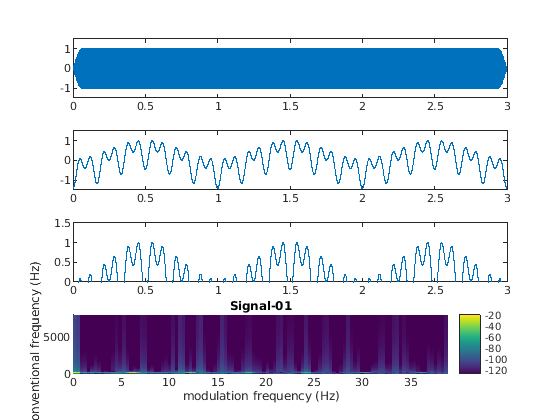

AMf1 = 1; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.5; % AM depth as a proportion of the carrier amplitude
AMphase1 = 1*pi;
mod = AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1);

% This is Full-Wave Rectification (1 cycle = 2 peaks)
%modFWR = abs(mod)./max(mod).*AMdepth1;
% Half-Wave Rectification (1 cycle = 1 peak)
hwr = mod>0;
modHWR = mod .* hwr;% ./max(mod).*AMdepth1;

% Compute effective modulation depending on depth
modHWR = modHWR + (1 - max(modHWR));

final = modHWR .* snd;
%final = modulate(snd, AMf, fs, 'am');

listen = audioplayer(final, fs);
playblocking(listen);

## Affichage

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, modHWR);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])


## Generate an amplitude modulation: 1 Hertz (1 cycle par seconde), Profondeur de modulation 25%

AMf1 = 1; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.25; % AM depth as a proportion of the carrier amplitude
AMphase1 = 0*pi;
mod = AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1);

% Half-Wave Rectification (1 cycle = 1 peak)
hwr = mod>0;
modHWR = mod .* hwr;% ./max(mod).*AMdepth1;

% Compute effective modulation depending on depth
modHWR = modHWR + (1 - max(modHWR));

final = modHWR .* snd;
%final = modulate(snd, AMf, fs, 'am');


## Affichage

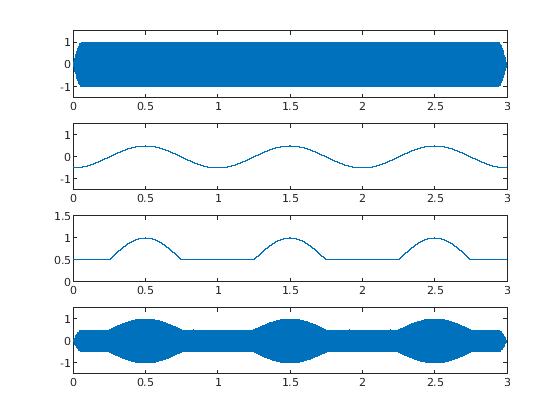

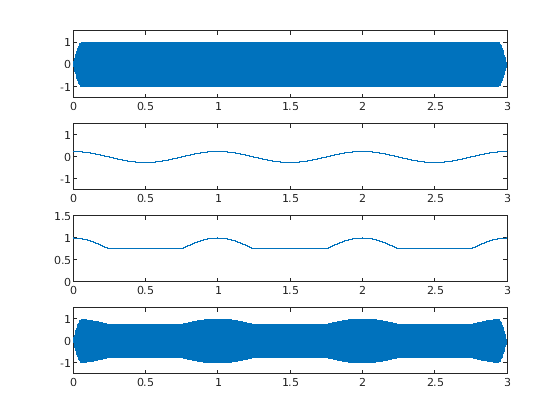

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, modHWR);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);

## Generate an amplitude modulation: 6 Hertz (6 cycles par seconde)

AMf1 = 6; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.25; % AM depth as a proportion of the carrier amplitude
AMphase1 = 0*pi;
mod = AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1);

% Half-Wave Rectification (1 cycle = 1 peak)
hwr = mod>0;
modHWR = mod .* hwr;% ./max(mod).*AMdepth1;

% Compute effective modulation depending on depth
modHWR = modHWR + (1 - max(modHWR));

final = modHWR .* snd;
%final = modulate(snd, AMf, fs, 'am');


## Affichage

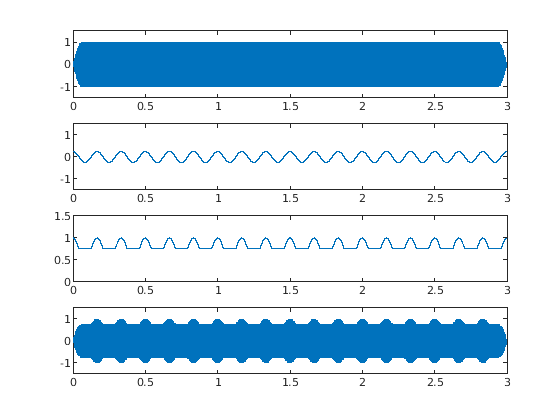

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, modHWR);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);

## Generate an amplitude modulation: 0.1 Hertz (0.1 cycle par seconde)

AMf1 = 0.1; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.5; % AM depth as a proportion of the carrier amplitude
AMphase1 = 0*pi;
AMamp = AMdepth1 * amp;
mod = AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1);

% Half-Wave Rectification (1 cycle = 1 peak)
hwr = mod>0;
modHWR = mod .* hwr;% ./max(mod).*AMdepth1;

% Compute effective modulation depending on depth
modHWR = modHWR + (1 - max(modHWR));

final = modHWR .* snd;
%final = modulate(snd, AMf, fs, 'am');


## Affichage

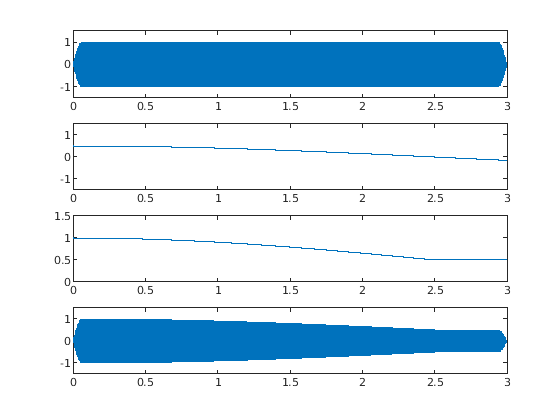

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, modHWR);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);